clc; clearvars;
addpath(genpath("functions"))
addpath overlap_functions\

Altitude grid and air number density

R = (1:8000).*3.75;
% R = [1 1000 3000 5000 10000];
R_km = R./1000;

N = airNumberDensity(R); % air number density at altitudes in R
Ns = surfaceAirDensity; % standard surface air density

No3 = zeros(size(R)); % ozone number density

Transmitter and receiver parameters

delta = 1;

laser_beamwaist = 0.0045; % w0
laser_divergence = 0.000167; % phi0

aperture_radius = 0.002; % a
obstruction_radius = 0.10016; % b
za = 0; % distance between focal plane and aperture

telescope_radius = 0.204; % R
telescope_focus = 1.905; % f 

lambda = 2.991e-7;

telescope_fov = aperture_radius / (telescope_focus + za) % half angle

telescope_fov = 0.0010

Lidar Equation


$$P(R)=K*G(R)*\beta(R)*T(R)$$


System Factor


$$K=P_0\frac{c\tau}{2}A\eta$$


tau = 6e-9;
E0 = 0.05;
eta = 0.0018;

N0 = E0./photonEnergy(lambda);

P0 = E0/tau;
A = pi * (telescope_radius^2 - obstruction_radius^2);

K = systemFactor(P0,tau,A,eta);

Geometric Factor


$$G(R)=\frac{O(R)}{R^2}$$


O = overlapFunc(R,laser_beamwaist, laser_divergence, aperture_radius, obstruction_radius, telescope_radius, telescope_focus, za, delta, "gaussian");
O_grid = R;
save("O_test.mat","O","O_grid");

G = geometricFactor(O,R);

Backscatter Coefficient


$$\beta(R,\lambda)=\sum_jN_j(R)\frac{d\sigma_{j,sca}}{d\Omega}(\pi,\lambda)$$


dc_rayleigh = rayleighBackscatterCross_Buckholtz(lambda);

dc = dc_rayleigh;

B = backScatter(dc_rayleigh,N);

Transmission Term


$$T(R,\lambda)=exp[-2\int_0^R\alpha(r,\lambda)dr]$$



$$\alpha(R,\lambda)=\sum_jN_j(R)\sigma_{j,ext}(\lambda)$$


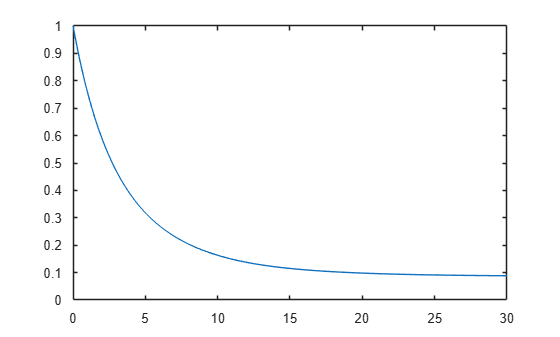

c_rayleigh = rayleighCross(lambda);
% disp(c_rayleigh *1e4)
% disp(c_rayleigh * Ns .*1e3);

co3 = 0;

alpha_rayleigh = sectionToCoefficient(c_rayleigh,N);
alpha_ozone = sectionToCoefficient(co3,No3);

alpha = alpha_rayleigh;
T = transmissionTerm(alpha',R');

figure;
plot(R_km,T)

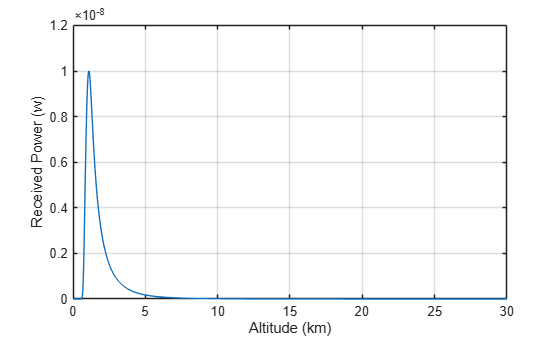

P = K .* G .* B .* T';

figure;
plot(R_km,P)
xlabel('Altitude (km)')
ylabel('Received Power (w)')
grid on;
ax = gca;
ax.MinorGridAlpha = 0;

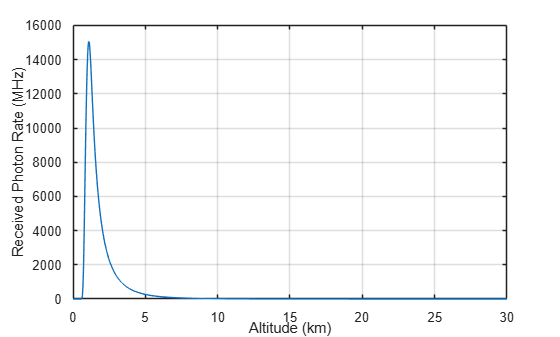

Np = P./photonEnergy(lambda) .*1e-6;

figure;
plot(R_km,Np)
xlabel('Altitude (km)')
ylabel('Received Photon Rate (MHz)')
grid on;
ax = gca;
ax.MinorGridAlpha = 0;

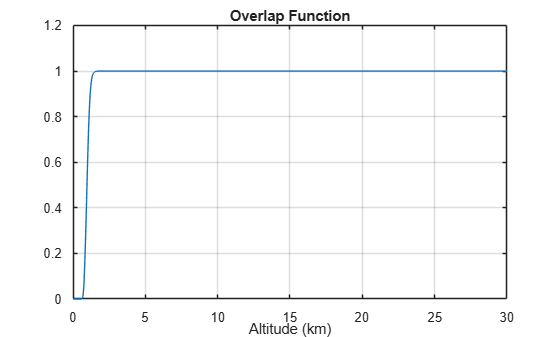

figure;
plot(R_km,O)
xlabel("Altitude (km)")
title("Overlap Function")
grid on

paramPath = "systemParam.mat";
params = struct;
params.R = R;
params.delta = delta;
params.laser_beamwaist = laser_beamwaist;
params.laser_divergence = laser_divergence;
params.aperture_radius = aperture_radius;
params.obstruction_radius = obstruction_radius;
params.za = za;
params.telescope_radius = telescope_radius;
params.telescope_focus = telescope_focus;
params.lambda = lambda;
params.tau = tau;
params.E0 = E0;
params.eta = eta;
params.N = N;
save(paramPath, '-struct', 'params');

% Np2 = simLidar(paramPath);

% figure;
% plot(R_km,Np2)
% xlabel('Altitude (km)')
% ylabel('Received Photon Rate (Hz)')
% grid on;
% ax = gca;
% ax.MinorGridAlpha = 0;

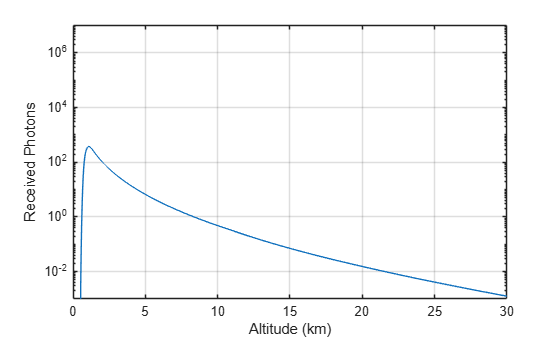

Ns = N0 .* eta .* G .* A .* 3.75 .* B .* T';
Ns(R<100) = NaN;

% save("Ns.mat","Ns");

figure;
semilogy(R_km,Ns)
xlabel('Altitude (km)')
ylabel('Received Photons')
grid on;
ax = gca;
ax.MinorGridAlpha = 0;
% xlim([0 10])
ylim([1e-3 1e7])